%compare beam squint compensation between different method
clc;
clear all;
close all;

%NantTX = [128,256,512];
TMax = (1e-12)*[320,340,400]

TMax = 	1.0e+-9 *

    0.3200    0.3400    0.4000


%TMax = 340e-12;

%% system parameters
Sysparam = struct();

Sysparam.Nt = 256;
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3*1e11;%carrier frequency 
Sysparam.f = 3*1e10; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 16; %number of TTDs for each RF chain
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
Sysparam.L = 1 ; % number of paths equals to number of RF chains
Sysparam.Q = 16; % number of fixed TTD element 
%% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 

%% simulation parameters
Simparam = struct();
Nloop = 50;
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.P = -20:5:15;% transmit power in dB
Simparam.Rho = 10.^(Simparam.P/10); %transmit power
Simparam.Niter = 50; %channel realizations
Simparam.phi = 0.2951*pi*ones(Sysparam.L,1)%AoD;

Simparam = struct with fields:
      psi: -1.2644
        P: [-20 -15 -10 -5 0 5 10 15]
      Rho: [0.0100 0.0316 0.1000 0.3162 1 3.1623 10 31.6228]
    Niter: 50
      phi: 0.9271


SpatialDirection = sin(Simparam.phi);

%Generate wideband channel
%H = WidebandChannel(Sysparam,Simparam);

for i = 1:length(TMax)
     
Sysparam.tmax = TMax(i);% maximum time-delay value
Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
[G1,G2k,x2,t2] = fixPSdesignTTD(Sysparam,Simparam); %Tan design
[PS,TTD,x,t] = jointPSandTTD(Sysparam, Simparam); % joint delay and phase precoding
%[S,F2k,D,~] = DynamicSubarray(Sysparam,Simparam,H,Nloop); %Dynamic subarray method
%%

for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,i) = abs(a(:,l)'*b(:,k,l)); %without compensation
         Compensated1(k,l,i) = abs((PS*TTD(:,l,k))'*b(:,k,l));
         Compensated2(k,l,i) = abs((G1*G2k(:,l,k))'*b(:,k,l));          
         %Compensated3(k,l,i) = abs((S*F2k(:,l,k))'*b(:,k,l));
    end
end
end 


set(0, 'defaultlinelinewidth', 3); set(0, 'defaultlinemarkersize', 8);
set(0, 'defaultaxesfontsize', 20); set(0, 'defaulttextfontsize', 20); 

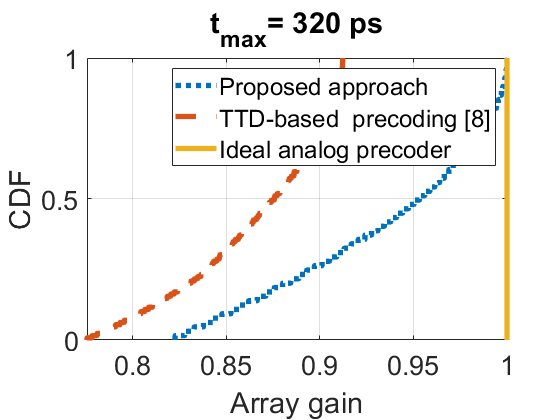

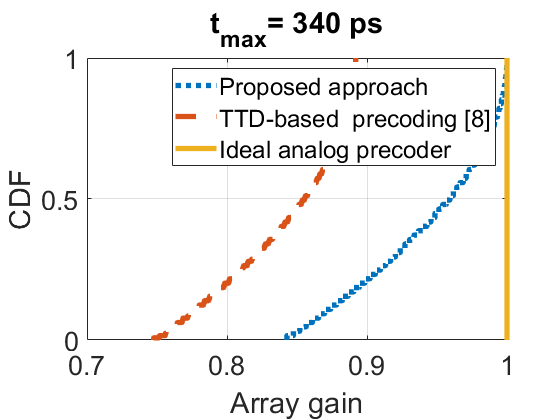

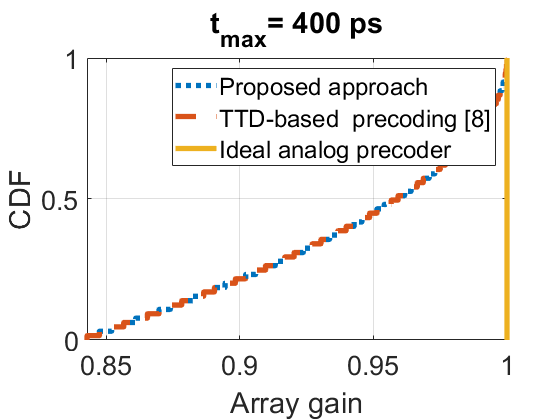

close all
for i = 1:length(TMax)
figure(i)
f1 = cdfplot(Compensated1(:,:,i));
set(f1,'LineWidth',4,'LineStyle',':','Marker','none');
hold on
f2 = cdfplot(Compensated2(:,:,i));
set(f2,'LineWidth',4,'LineStyle','--','Marker','none');
hold on
% f3 = cdfplot(Compensated3(:,:,1));
% set(f3,'LineWidth',4,'LineStyle','--','Marker','none');
% hold on
f4 = cdfplot(ones(Sysparam.K,1));
set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
%legend('Proposed approach','TTD-based  precoding [8]','TTD-based  precoding [11]','Ideal analog precoder')
legend('Proposed approach','TTD-based  precoding [8]','Ideal analog precoder')
xlabel('Array gain')
ylabel('CDF')
%title('')
title("t_{max}= "+ TMax(i)*1e12+" ps");
end